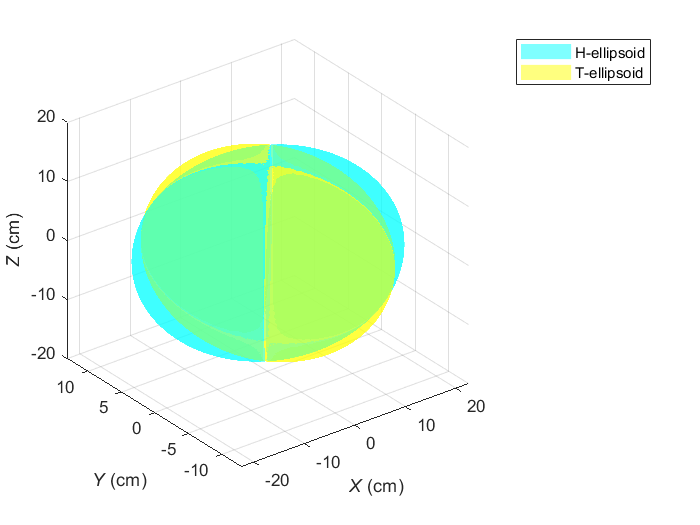

load BFCS_E1E2E3.mat
[x1, y1, z1] = ellipsoid(0,0,0,double(H/I1),double(H/I2),double(H/I3),100);
[x2, y2, z2] = ellipsoid(0,0,0,double(sqrt(2*K/I1)),double(sqrt(2*K/I2)),double(sqrt(2*K/I3)),100);


H_ellipsoid = surfl(z1, x1, y1); 
set(H_ellipsoid, 'FaceAlpha', 0.5, 'FaceColor', 'c', 'EdgeColor', 'none');
%H_ellipsoid.EdgeColor = 'none';
hold on;
T_ellipsoid = surfl(z2, x2, y2); 
set(T_ellipsoid, 'FaceAlpha', 0.5,  'FaceColor', 'y', 'EdgeColor', 'none');
%T_ellipsoid.EdgeColor = 'none';
xlabel('\itX\rm (cm)');
ylabel('\itY\rm (cm)');
zlabel('\itZ\rm (cm)');
legend("H-ellipsoid","T-ellipsoid");
hold off;